instances=strings(12,1);
for i=1:12
    instances(i)="mtVRP"+string(i);
end
path="";
CotasInf=[403.0798
          494.7108
          519.1544
          544.8263
          576.5399
          576.5399
          581.1548
          591.8548
          591.8548
          342.5924
          419.6528
          419.6528];


Alg="ACO";
Obj=[];
Tiempo=[];
F=[];
n=9;
for j=1:12
    Instance=j;
    NObj=[];
    NF=[];
    AuxT=[];
    for i=1:n
        D=xlsread(path+"\mtVRP_FHenao_"+Alg+string(i)+".xlsx",Instance);
        NObj=[NObj D(end,1)];
        AuxT=[AuxT D(end,2)];
        Aux=D(1:end-1,end);
        Penalizacion=500*ones(1,size(Aux,1))*Aux;
        NF=[NF Penalizacion];
    end
    F=[F
        NF];
    Obj=[Obj
        NObj];
    Tiempo=[Tiempo
            AuxT];
end

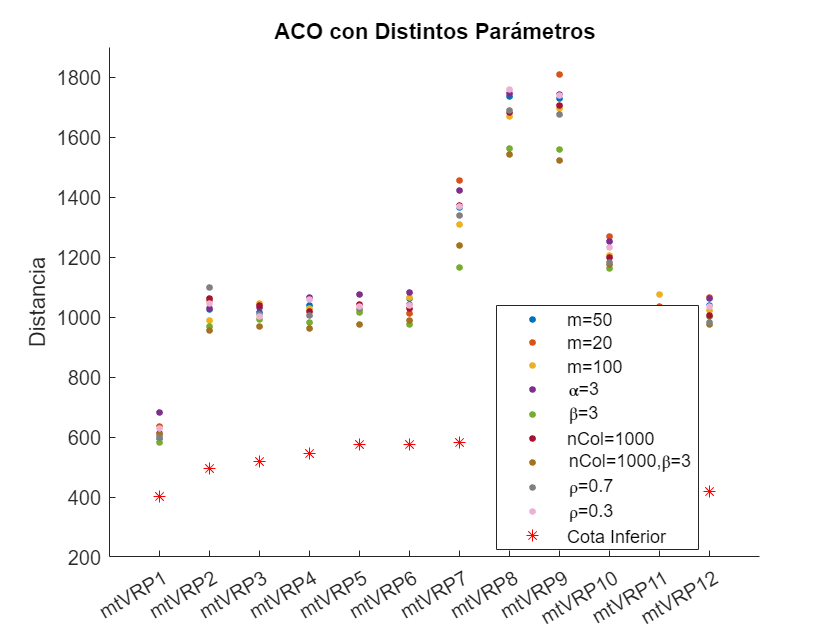

names={'m=50','m=20','m=100','\alpha=3','\beta=3','nCol=1000','nCol=1000,\beta=3','\rho=0.7','\rho=0.3','Cota Inferior'};
colors = [0, 0.4470, 0.7410;   % Blue
    0.8500, 0.3250, 0.0980;   % Orange    
    0.9290, 0.6940, 0.1250;   % Yellow    
    0.4940, 0.1840, 0.5560;   % Purple    
    0.4660, 0.6740, 0.1880;   % Green    
    0.6350, 0.0780, 0.1840;   % Red    
    0.6350, 0.4470, 0.1250;   % Brown    
    0.5, 0.5, 0.5;   % Gray    
    0.9290, 0.6940, 0.8390    % Pink
    ];
figure; hold on
for i=1:n
    plot([Obj(:,i)],'.', 'markersize', 10, 'Color',colors(i,:))
end
plot(CotasInf,'r*')
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([round(min(CotasInf,[],'all'),-2)-100 round(max(Obj,[],'all'),-2)+100])
title("ACO con Distintos Parámetros")
ylabel("Distancia")
legend(names,"Location",'best')

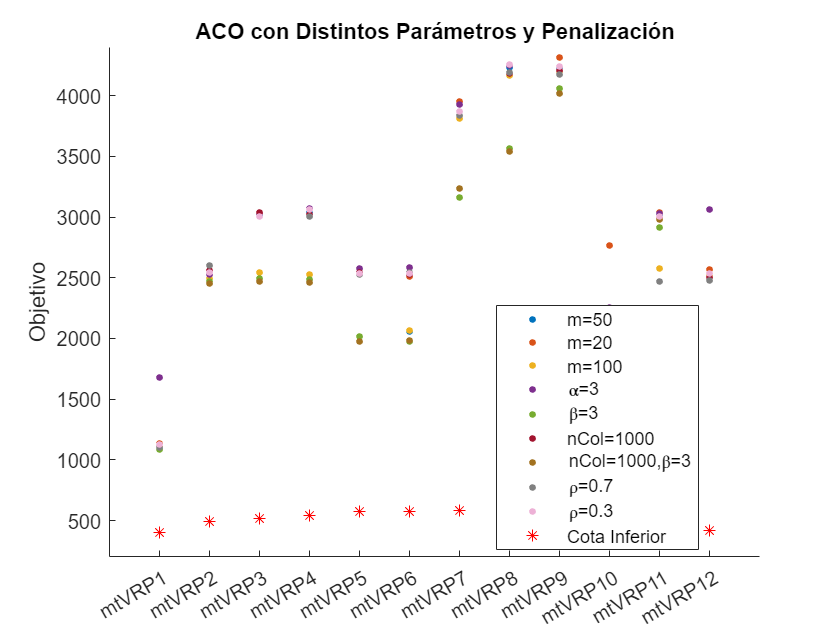

%Agregando Penalización
ObjP=Obj+F;
figure; hold on
for i=1:9
    plot([ObjP(:,i)],'.', 'markersize', 10, 'Color',colors(i,:))
end
plot(CotasInf,'r*')
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([round(min(CotasInf,[],'all'),-2)-100 round(max(ObjP,[],'all'),-2)+100])
title("ACO con Distintos Parámetros y Penalización")
ylabel("Objetivo")
legend(names,"Location",'best')

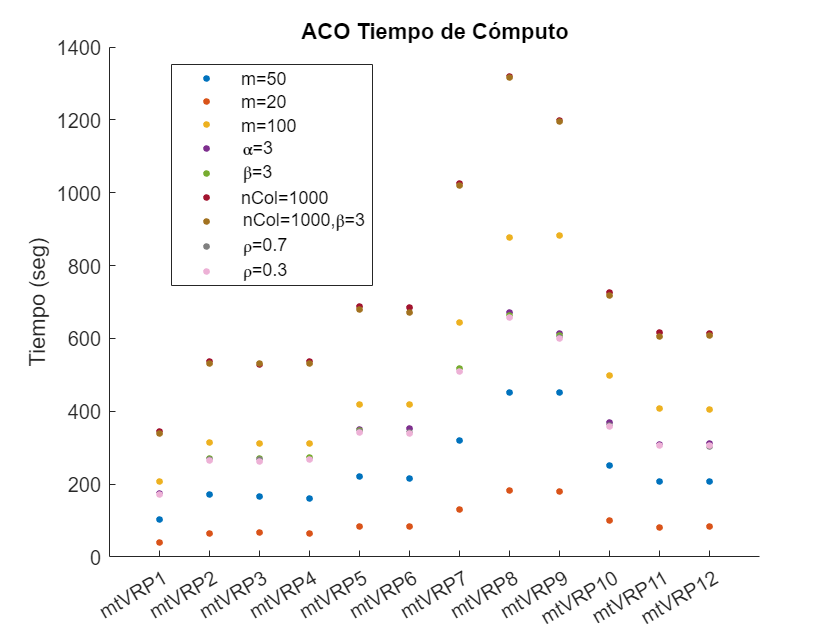

% Tiempo ACO
namesT={'m=50','m=20','m=100','\alpha=3','\beta=3','nCol=1000','nCol=1000,\beta=3','\rho=0.7','\rho=0.3'};
figure; hold on
for i=1:n
    plot([Tiempo(:,i)],'.', 'markersize', 10, 'Color',colors(i,:))
end
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([0 round(max(Tiempo,[],'all'),-2)+100])
title("ACO Tiempo de Cómputo")
ylabel("Tiempo (seg)")
legend(namesT,"Location",'best')

Alg=["Constructivo","GRASP","ACO"];
Obj=[];
Tiempo=[];
F=[];
for j=1:12
    Instance=j;
    NObj=[];
    NF=[];
    AuxT=[];
    for i=1:3
        D=xlsread(path+"\mtVRP_FHenao_"+Alg(i)+".xlsx",Instance);
        NObj=[NObj D(end,1)];
        AuxT=[AuxT D(end,2)];
        Aux=D(1:end-1,end);
        Penalizacion=500*ones(1,size(Aux,1))*Aux;
        NF=[NF Penalizacion];
    end
    F=[F
        NF];
    Obj=[Obj
        NObj];
    Tiempo=[Tiempo
            AuxT];
end

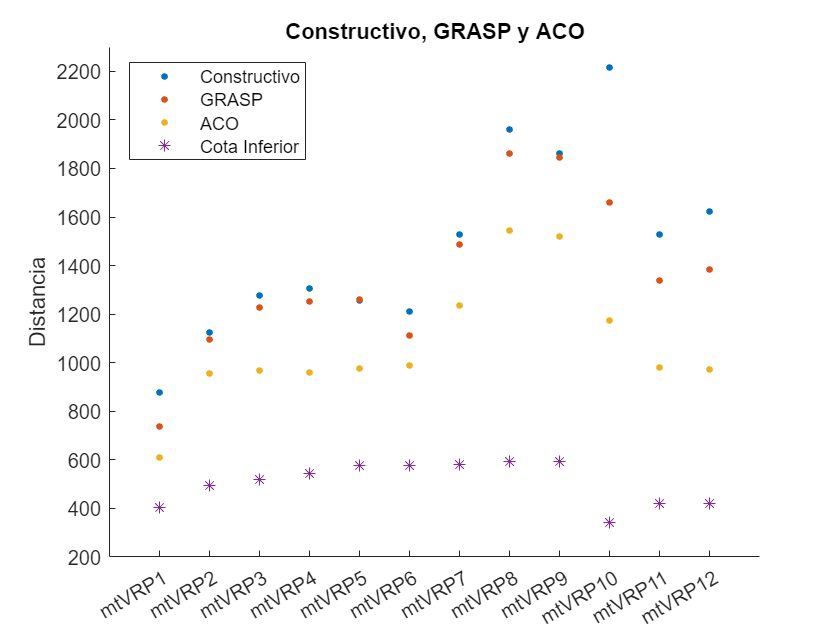

names={'Constructivo','GRASP','ACO','Cota Inferior'};
figure; hold on
for i=1:3
    plot([Obj(:,i)],'.', 'markersize', 10)
end
plot(CotasInf,'*')
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([round(min(CotasInf,[],'all'),-2)-100 round(max(Obj,[],'all'),-2)+100])
title("Constructivo, GRASP y ACO")
ylabel("Distancia")
legend(names,"Location",'best')

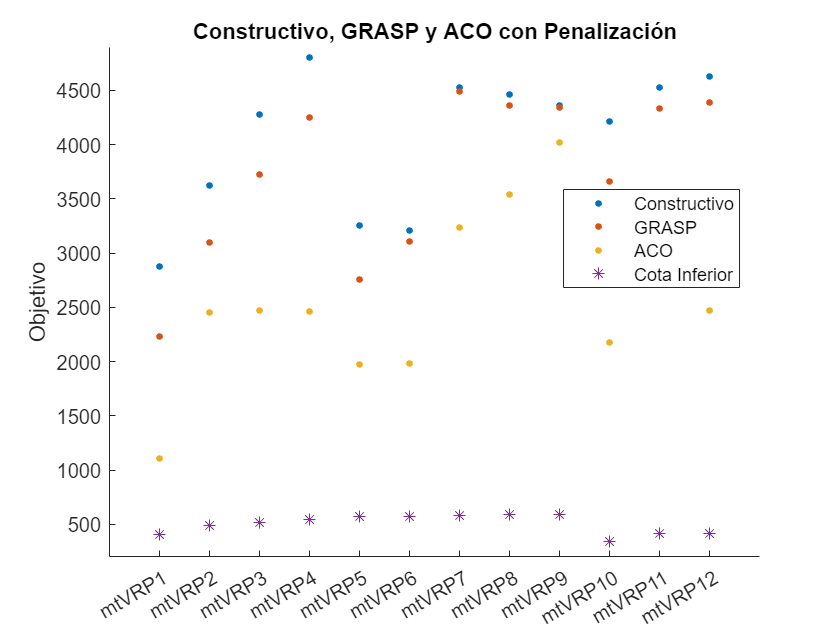

%Agregando Penalización
ObjP=Obj+F;
figure; hold on
for i=1:3
    plot([ObjP(:,i)],'.', 'markersize', 10)
end
plot(CotasInf,'*')
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([round(min(CotasInf,[],'all'),-2)-100 round(max(ObjP,[],'all'),-2)+100])
title("Constructivo, GRASP y ACO con Penalización")
ylabel("Objetivo")
legend(names,"Location",'best')

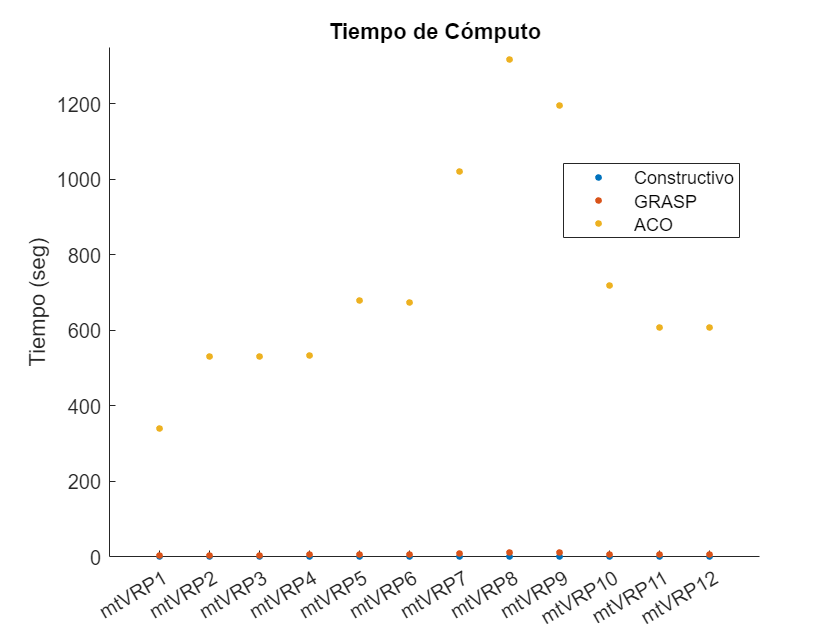

% Tiempo 
namesT={'Constructivo','GRASP','ACO'};
figure; hold on
for i=1:3
    plot([Tiempo(:,i)],'.', 'markersize', 10)
end
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([0 round(max(Tiempo,[],'all'),-2)+50]) 
title("Tiempo de Cómputo")
ylabel("Tiempo (seg)")
legend(namesT,"Location",'best')

Alg="GRASP";
Obj=[];
Tiempo=[];
F=[];
n=9;
for j=1:12
    Instance=j;
    NObj=[];
    NF=[];
    AuxT=[];
    for i=1:n
        D=xlsread(path+"\mtVRP_FHenao_"+Alg+string(i)+".xlsx",Instance);
        NObj=[NObj D(end,1)];
        AuxT=[AuxT D(end,2)];
        Aux=D(1:end-1,end);
        Penalizacion=500*ones(1,size(Aux,1))*Aux;
        NF=[NF Penalizacion];
    end
    F=[F
        NF];
    Obj=[Obj
        NObj];
    Tiempo=[Tiempo
            AuxT];
end

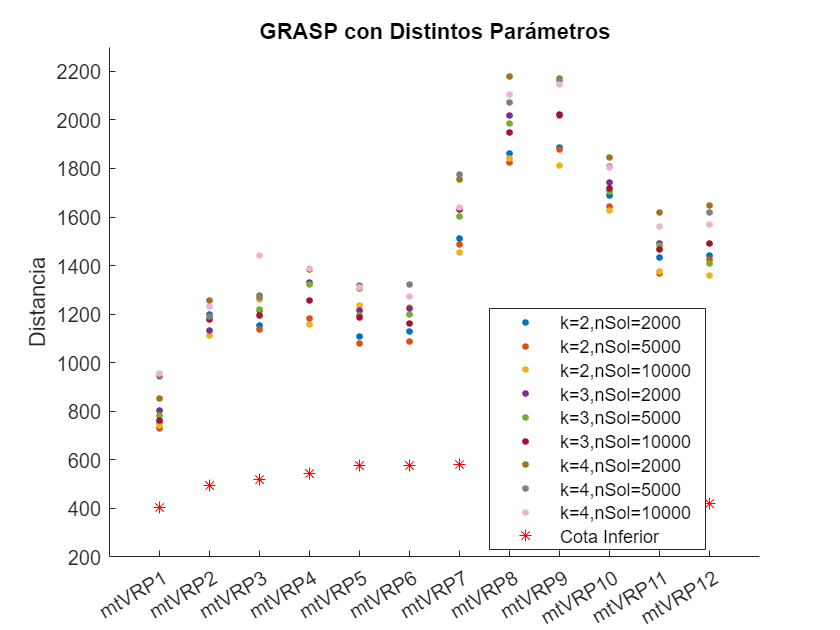

names={'k=2,nSol=2000','k=2,nSol=5000','k=2,nSol=10000','k=3,nSol=2000','k=3,nSol=5000',...
    'k=3,nSol=10000','k=4,nSol=2000','k=4,nSol=5000','k=4,nSol=10000','Cota Inferior'};
colors = [0, 0.4470, 0.7410;   % Blue
    0.8500, 0.3250, 0.0980;   % Orange    
    0.9290, 0.6940, 0.1250;   % Yellow    
    0.4940, 0.1840, 0.5560;   % Purple    
    0.4660, 0.6740, 0.1880;   % Green    
    0.6350, 0.0780, 0.1840;   % Red    
    0.6350, 0.4470, 0.1250;   % Brown    
    0.5, 0.5, 0.5;   % Gray    
    0.9290, 0.6940, 0.8390    % Pink
    ];
figure; hold on
for i=1:n
    plot([Obj(:,i)],'.', 'markersize', 10, 'Color',colors(i,:))
end
plot(CotasInf,'*r')
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([round(min(CotasInf,[],'all'),-2)-100 round(max(Obj,[],'all'),-2)+100])
title("GRASP con Distintos Parámetros")
ylabel("Distancia")
legend(names,"Location",'best')

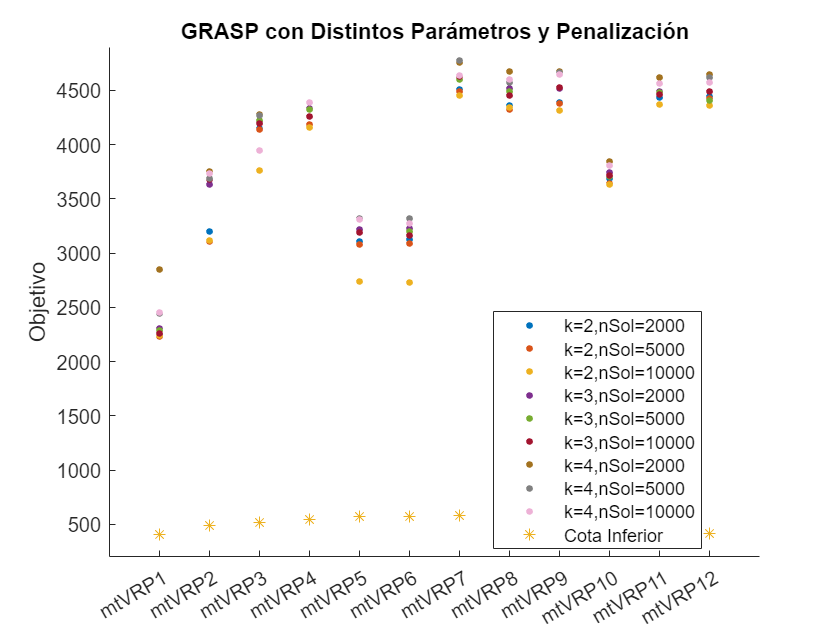

%Agregando Penalización
ObjP=Obj+F;
figure; hold on
for i=1:n
    plot([ObjP(:,i)],'.', 'markersize', 10, 'Color',colors(i,:))
end
plot(CotasInf,'*')
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([round(min(CotasInf,[],'all'),-2)-100 round(max(ObjP,[],'all'),-2)+100])
title("GRASP con Distintos Parámetros y Penalización")
ylabel("Objetivo")
legend(names,"Location",'best')

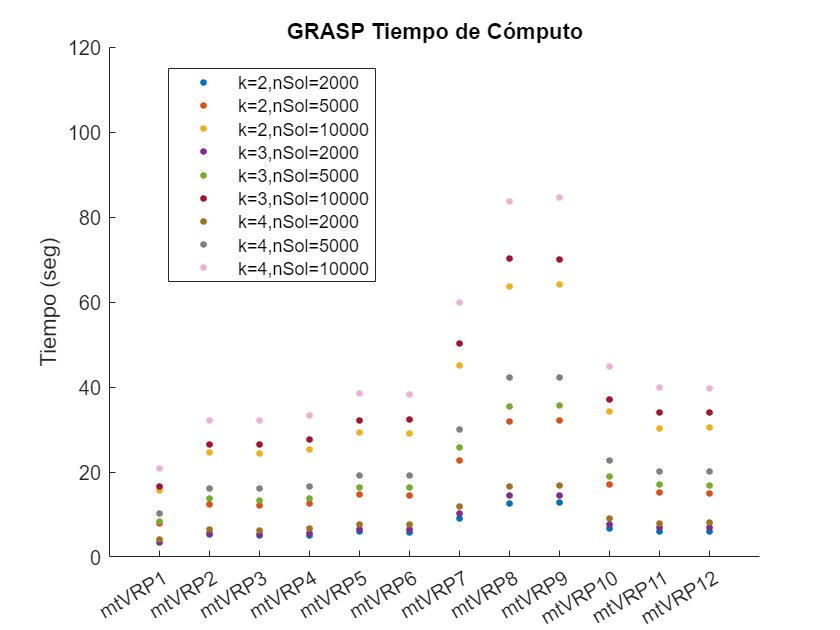

% Tiempo GRASP
namesT={'k=2,nSol=2000','k=2,nSol=5000','k=2,nSol=10000','k=3,nSol=2000','k=3,nSol=5000',...
    'k=3,nSol=10000','k=4,nSol=2000','k=4,nSol=5000','k=4,nSol=10000'};
figure; hold on
for i=1:n
    plot([Tiempo(:,i)],'.', 'markersize', 10, 'Color',colors(i,:))
end
xticks(1:12)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([0 round(max(Tiempo,[],'all'),-2)+20])
title("GRASP Tiempo de Cómputo")
ylabel("Tiempo (seg)")
legend(namesT,"Location",'best')